# Métodos iterativos para Sistemas de ecuaciones lineales

## Descomposición matricial

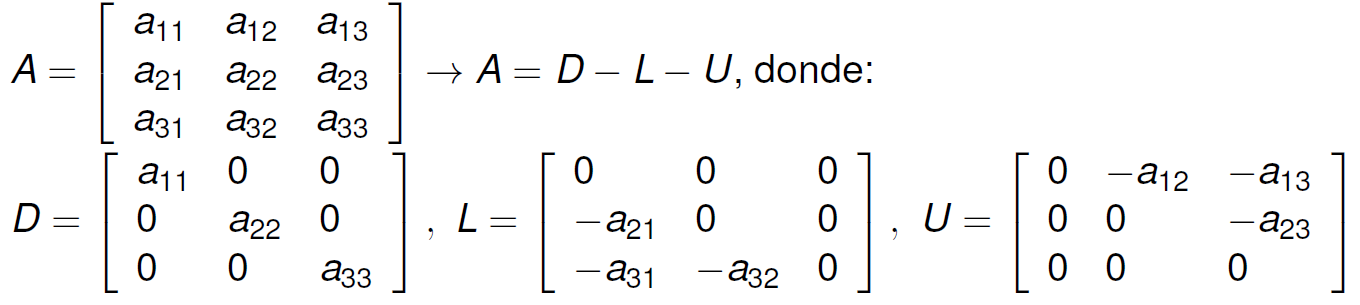

A = [3 1 0;
    1 3 1;
    0 1 3]

A =      3     1     0
     1     3     1
     0     1     3


b = [10; 20; 30];
% A = D -L -U
D = diag(diag(A));
L = -tril(A,-1);
U = -triu(A,1);
(D-L-U) - A

ans =      0     0     0
     0     0     0
     0     0     0


## Métodos iterativos: forma matricial


$$Ax=b$$


$x^{(0)}$=dato


$$x^{(k+1)}=Tx^{(k)}+c$$


### Jacobi


$$T=D^{-1}(L+U), \quad c=D^{-1}b$$


T_j = inv(D)*(L+U)

T_j =          0   -0.3333         0
   -0.3333         0   -0.3333
         0   -0.3333         0


c_j = inv(D)*b

c_j =     3.3333
    6.6667
   10.0000


x0 = [0;0;0];
x1 = T_j * x0 + c_j;
x2 = T_j * x1 + c_j;
[x0'; x1'; x2']

ans =          0         0         0
    3.3333    6.6667   10.0000
    1.1111    2.2222    7.7778


### Gauss-Seidel


$$T_{gs} = {(D-L)}^{-1}U, \quad c_{gs}={(D-L)}^{-1}b$$


T_gs = inv(D-L)*U

T_gs =          0   -0.3333         0
         0    0.1111   -0.3333
         0   -0.0370    0.1111


c_gs = inv(D-L)*b

c_gs =     3.3333
    5.5556
    8.1481


x0 = [0;0;0];
x1 = T_gs * x0 + c_gs;
x2 = T_gs * x1 + c_gs;
[x0'; x1'; x2']

ans =          0         0         0
    3.3333    5.5556    8.1481
    1.4815    3.4568    8.8477


## Implementación como función

### Jacobi

A; b; x0;
Tol = 0.01

Tol = 0.0100

z = iterativo(A,b,x0,Tol)

z =          0         0         0    1.0000
    3.3333    6.6667   10.0000    1.0000
    1.1111    2.2222    7.7778    0.5714
    2.5926    3.7037    9.2593    0.1600
    2.0988    2.7160    8.7654    0.1127
    2.4280    3.0453    9.0947    0.0362
    2.3182    2.8258    8.9849    0.0244
    2.3914    2.8989    9.0581    0.0081


x_j = z(end,1:3)

x_j =     2.3914    2.8989    9.0581


error_j = z(end,end)

error_j = 0.0081

Jacobi necesita 7 iteraciones

### Gauss-Seidel

method=1; % para G-S
z=iterativo(A,b,x0,Tol,method)

z =          0         0         0    1.0000
    3.3333    5.5556    8.1481    1.0000
    1.4815    3.4568    8.8477    0.2372
    2.1811    2.9904    9.0032    0.0777
    2.3365    2.8868    9.0377    0.0172
    2.3711    2.8637    9.0454    0.0038


x_gs = z(end,1:3)

x_gs =     2.3711    2.8637    9.0454


error_gs = z(end,end)

error_gs = 0.0038

Gauss-Seidel necesita 5 iteraciones

- Ambos métodos convergen

- G-S converge más rápido que Jacobi

### Comparación entre métodos

Respecto de las estimaciones propias del error

[x_j error_j]

ans =     2.3914    2.8989    9.0581    0.0081


[x_gs error_gs]

ans =     2.3711    2.8637    9.0454    0.0038


Respecto del valor exacto

x_exac = A \ b; x_exac'

ans =     2.3810    2.8571    9.0476


error_j = norm(x_exac - x_j,inf)

error_j = 12.8153

error_gs = norm(x_exac - x_gs,inf) 

error_gs = 12.8626

function [z,T,c]=iterativo(A,b,x0,Tol,method)
% method: variable numérica
% method=0: Jacobi
% method=1: Gauss-Seidel

% Valor por defecto para esquema
if nargin<5
    method=0;
end

% Construir T, c
D=diag(diag(A));
L=-tril(A,-1);
U=-triu(A,1);

if method==0
    % Jacobi
    T_j=inv(D)*(L+U);
    c_j=inv(D)*b;
elseif method==1
    % Gauss-Seidel
    T_gs=inv(D-L)*(U);
    c_gs=inv(D-L)*b;
else
    error('Escoja un equema válido: 0 (Jacobi), 1 (Gauss-Seidel)')
end

% Inicialización
er=1;
z=[x0' er];

while er > Tol
    x1=T*x0+c;
    er=norm(x1-x0,inf)/norm(x1,inf);
    z=[z;x1' er];
    x0=x1;
end
end